clear
close all
L=1e-4;
Kt = 0.0504*1;Ke = Kt;
Ra = 1.2*1;
B = 2.9e-5*1; %sintonizada

JpoleaConductora=0.06754e-4;
Jext=33.74e-4;
Kb = (Ke / (2 * pi * Kt));
L = (Ke * Kb) / Ra;
Jout=5e-3;

m=(35*0.001)*pi*(17*0.001)^2*8966

Jm=0.5*m*(17*0.001)^2/1.2



N=2;
Jt=Jm+JpoleaConductora+(Jext)/N^2;

Rinercia=(JpoleaConductora+(Jext)/N^2)/Jm
Vi=0;Vf=24;
t0=0;tf=5;





[qd, vd, ad] = perfil_movimiento(q0, v0, ac0, q1, v1, ac1, t0, tf, npoints)

nPuntos=251
[Time, V_PWM]=perfil_voltaje(0, 0, 0, 24, 0, 0, t0, 5, nPuntos)


plot(Time,V_PWM)
grid on
xlabel("t (s)")
ylabel("Voltaje (V)")
title("Perfil de voltaje máximo del motor")


clk=4000000;PWM=4000;TMR2_prescaler=1;PR2=clk/(4*PWM*TMR2_prescaler)-1

PR2 = 249


sensibilidad=24/PR2

sensibilidad = 0.0964

nPuntos=251

nPuntos = 251


[Time, V_PWM]=perfil_voltaje(Vi/24*PR2, 0, 0, Vf/24*PR2, 0, 0, t0, tf,nPuntos);

M =            1           0           0           0           0           0
           0           1           0           0           0           0
           0           0           2           0           0           0
           1           5          25         125         625        3125
           0           1          10          75         500        3125
           0           0           2          30         300        2500


b =      0
     0
     0
   249
     0
     0


a =          0
         0
         0
   19.9200
   -5.9760
    0.4781


ts=tf/(nPuntos-1)*1000;
duty=100*0.01;

V_PWM=round(V_PWM*duty,0)/PR2*24;

%scatter(Time,V_PWM,".")



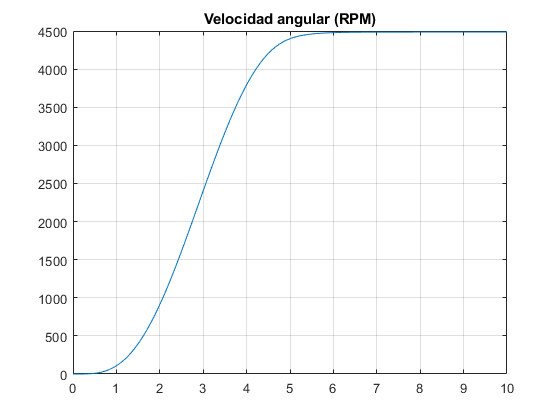


Vprofile=[Time, V_PWM];

sim("modelo.slx")


figure(8)
plot(qd.Time,qd.Data)
title("Velocidad angular (RPM)")
grid on

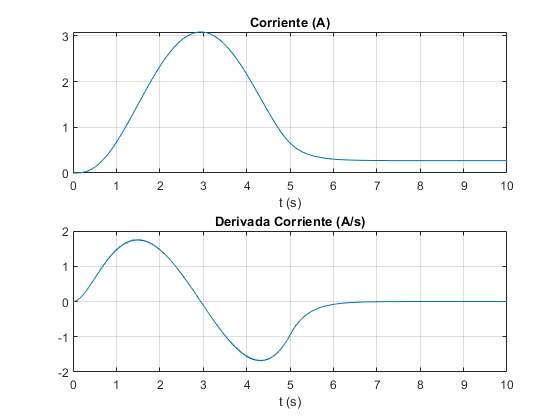



figure(4)

subplot(2,1,1)
plot(I.Time,I.data)
xlabel("t (s)")
title("Corriente (A)")
%ylim([0.2 0.3])
grid on

subplot(2,1,2)
plot(Id.Time,Id.data)
xlabel("t (s)")
title("Derivada Corriente (A/s)")
grid on

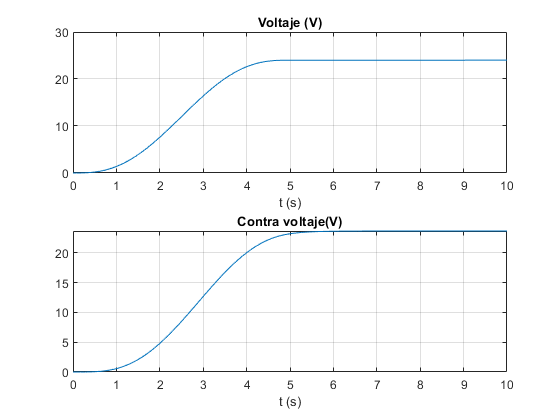



figure(1)

subplot(2,1,1)
plot(Vprof.Time,Vprof.data)
xlabel("t (s)")
title("Voltaje (V)")
grid on


subplot(2,1,2)
plot(Vcontra.Time,Vcontra.data)
xlabel("t (s)")
title("Contra voltaje(V)")
grid on

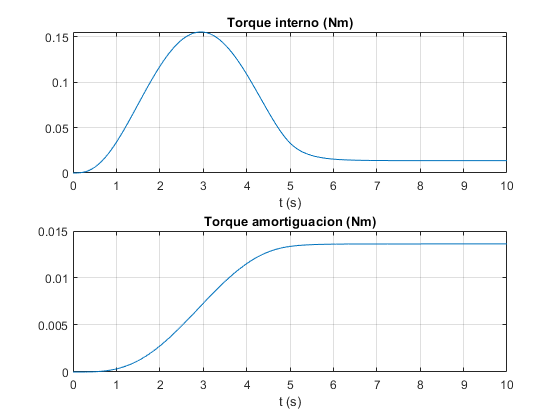



figure(3)








figure(5)
subplot(2,1,1)
plot(Tau_in.Time,Tau_in.data)
title("Torque interno (Nm)")
xlabel("t (s)")
grid on


subplot(2,1,2)
plot(Tamor.Time,Tamor.data)
title("Torque amortiguacion (Nm)")
xlabel("t (s)")
grid on

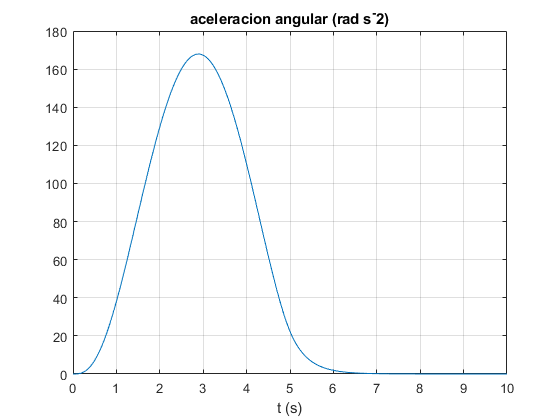


figure(7)
plot(qdd.Time,qdd.data)
title("aceleracion angular (rad s^-2)")
xlabel("t (s)")
grid on

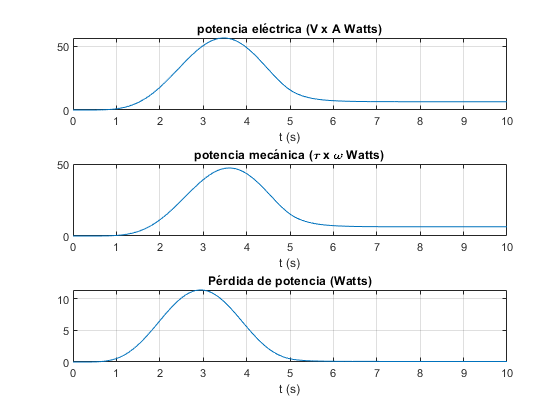



figure(9)

subplot(3,1,1)
plot(potenciaElec.Time,potenciaElec.data)
title("potencia eléctrica (V x A Watts)")
xlabel("t (s)")
grid on


subplot(3,1,2)
plot(potenciaMec.Time,potenciaMec.data)
title("potencia mecánica (\tau x \omega Watts)")
xlabel("t (s)")
grid on




subplot(3,1,3)
plot(potenciaElec.Time,potenciaElec.data-potenciaMec.data)
title("Pérdida de potencia (Watts)")
xlabel("t (s)")
grid on

function [qd, vd, ad] = perfil_movimiento(q0, v0, ac0, q1, v1, ac1, t0, tf, npoints)

t = linspace(t0, tf, npoints);
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
      0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
      0 0 2 6*t0 12*t0^2 20*t0^3;
      1 tf tf^2 tf^3 tf^4 tf^5;
      0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
      0 0 2 6*tf 12*tf^2 20*tf^3];

b = [q0; v0; ac0; q1; v1; ac1];
a = M^-1 * b;

qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;
vd = a(2).*c +2*a(3).*t +3*a(4).*t.^2 +4*a(5).*t.^3 +5*a(6).*t.^4;
ad = 2*a(3).*c + 6*a(4).*t +12*a(5).*t.^2 +20*a(6).*t.^3;

end


function [t,qd] = perfil_voltaje(q0, v0, ac0, q1, v1, ac1, t0, tf, npoints)

t = linspace(t0, tf, npoints)';
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
      0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
      0 0 2 6*t0 12*t0^2 20*t0^3;
      1 tf tf^2 tf^3 tf^4 tf^5;
      0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
      0 0 2 6*tf 12*tf^2 20*tf^3]

b = [q0; v0; ac0; q1; v1; ac1]
a = M^-1 * b

qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;

end


function [t,qd] = perfil_voltaje_C(q0, q1, tf, npoints)

t = linspace(0, tf, npoints)';
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
      0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
      0 0 2 6*t0 12*t0^2 20*t0^3;
      1 tf tf^2 tf^3 tf^4 tf^5;
      0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
      0 0 2 6*tf 12*tf^2 20*tf^3];

b = [q0; 0; 0; q1; 0; 0];
a = M^-1 * b;

qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;

end









